### Carregando imagens

image_goi1 = 'goi1.jpg';
image_goi2 = 'goi2.jpg';

### Obtendo os keypoints com a função sift.m fornecida

[img_goi1, descriptors_goi1, locs_goi1] = sift(image_goi1);

Finding keypoints... 
1146 keypoints found. 


[img_goi2, descriptors_goi2, locs_goi2] = sift(image_goi2);

Finding keypoints... 
1249 keypoints found. 


### Encontrando os matches dos pontos entre as imagens

matches_goi = findMatches1(descriptors_goi1, descriptors_goi2);

### Plot das correspondências

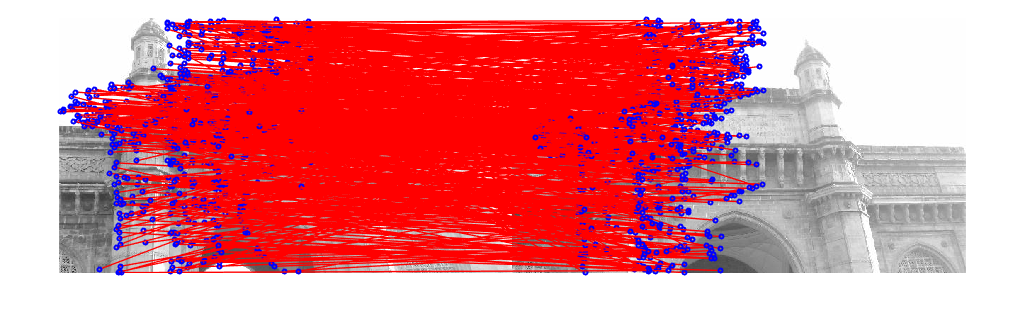

keypoints_goi1 = round(locs_goi1(:,1:2));
keypoints_goi2 = round(locs_goi2(:,1:2));
plotMatches(img_goi1, img_goi2, keypoints_goi1, keypoints_goi2, matches_goi);

### Calculando a Homografia entre as duas imagens com o RANSAC

H_goi = ransac(keypoints_goi1, keypoints_goi2, matches_goi)

H_goi =     0.9306   -0.0656   34.0136
   -0.0439    0.8901   52.4501
   -0.0001   -0.0002    1.0000


### Plotando as imagens lado a lado

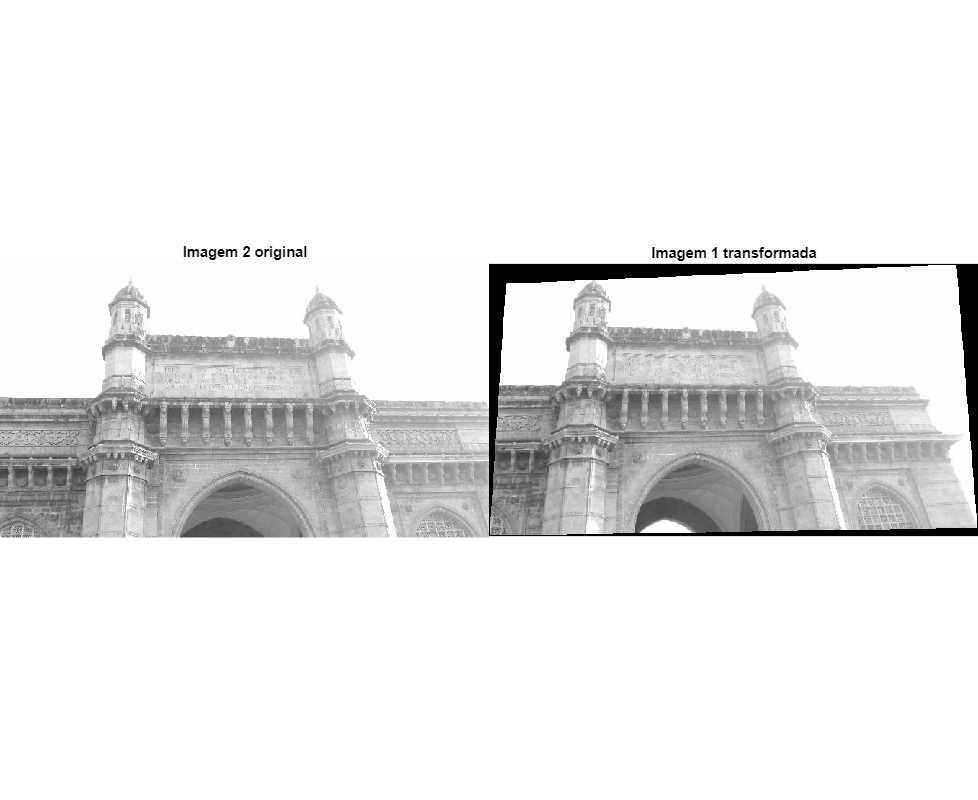

transform_goi = projtform2d(H_goi);
img_goi_proj  = imwarp(img_goi1, transform_goi); % Aplicando a homografia na imagem 1

figure('Position', [0, 0, 1100, 900]);
subplot(1, 2, 1);
imshow(img_goi2);
title('Imagem 2 original')
subplot(1, 2, 2);
imshow(img_goi_proj);
title('Imagem 1 transformada')
hold on;
set(subplot(1, 2, 1), 'Position', [0, 0, 0.5, 1]);
set(subplot(1, 2, 2), 'Position', [0.5, 0, 0.5, 1]); 
set(gca, 'LooseInset', get(gca, 'TightInset')); 

### Superpondo as imagens

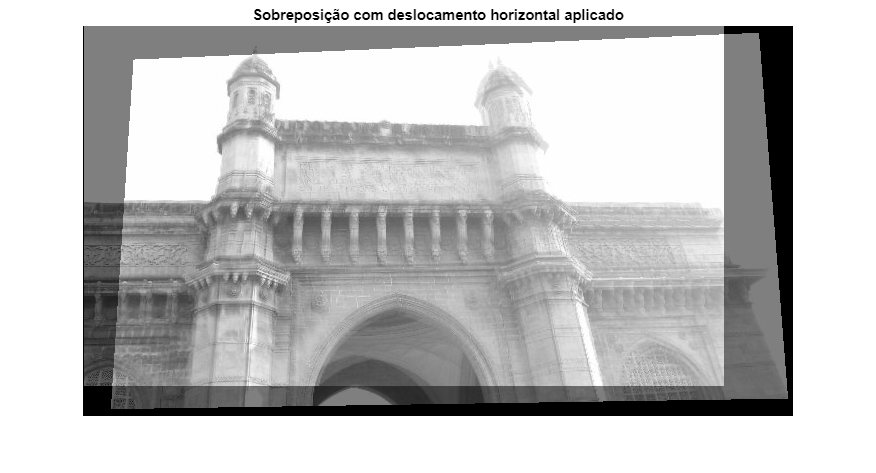

% Tamanho das imagens
[h1, w1] = size(img_goi2);
[h2, w2] = size(img_goi_proj);

% Offsets
vertical_offset   = 6; 
horizontal_offset = 27; 

% Tamanho do canvas
canvas_width  = 710;
canvas_height = 390;

% Canvas em branco para as imagens 
canvas1 = uint8(zeros(canvas_height, canvas_width));
canvas2 = uint8(zeros(canvas_height, canvas_width));

% Inserindo as imagens nos canvas
canvas1(1:h1,2:w1+1) = img_goi2;
canvas2(1+vertical_offset:h2+vertical_offset, 1+horizontal_offset:w2+horizontal_offset) = img_goi_proj;
 
alpha = 0.5; % Transparência
overlay_img = uint8(alpha * double(canvas1) + (1 - alpha) * double(canvas2)); % Superpondo as imagens

figure;
imshow(overlay_img);
title('Sobreposição com deslocamento horizontal aplicado');

Como é possível verificar a homografia obtida aproximou de forma razoável a primeira imagem da segunda, a superposição apresentou uma imagem aproximadamente contínua e relativamente bem definida.

## Funcões utilizadas

#### RANSAC

function best_H = ransac(keypts1, keypts2, matches)
    N = 2000;               % Número de iterações
    threshold = 1;          % Limiar para considerar inliers
    best_inliers = 0;
    
    % Normalizando os pontos
    [keypts1_norm, T1] = normalize_points(keypts1);
    [keypts2_norm, T2] = normalize_points(keypts2);
    
    sampled_sets = zeros(N, 4); % Registar conjuntos já amostrados para evitar repetição
    
    for i = 1:N
        unique_subset = false;
        while ~unique_subset
            indices = randperm(size(matches, 1), 4);
            indices = sort(indices); % Ordenar para facilitar a comparação
            
            % Verificando se este subconjunto já foi amostrado
            if ~ismember(indices, sampled_sets, 'rows')
                pts1 = keypts1_norm(matches(indices, 1), :); 

                if ~is_collinear(pts1)  % Verificando colinearidade entre os pontos
                    unique_subset = true;
                    sampled_sets(i, :) = indices; % Armazenando o subconjunto amostrado
                end
            end
        end
        
        pts1 = keypts1_norm(matches(indices, 1), :); 
        pts2 = keypts2_norm(matches(indices, 2), :); 

        % Montando a matriz A(DLT)
        A = zeros(8, 9);
        for j = 1:4
            x1 = pts1(j, 1); 
            y1 = pts1(j, 2);
            x2 = pts2(j, 1); 
            y2 = pts2(j, 2);

            A(2*j-1, :) = [x1, y1, 1, 0, 0, 0, -x1*x2, -y1*x2, -x2];
            A(2*j, :)   = [0, 0, 0, x1, y1, 1, -x1*y2, -y1*y2, -y2];
        end

        % Calculando a homografia 
        [~, ~, V] = svd(A);
        h = V(:, end);
        H = reshape(h, [3, 3])';
        H = T2 \ H * T1;
        H = H / H(3, 3);

        num_inliers = 0;
        for k = 1:size(matches, 1)
            pt1 = [keypts1(matches(k, 1), :) 1]';
            pt2 = [keypts2(matches(k, 2), :) 1]';

            proj_pt2 = H * pt1;                     % Cálculo do erro de transferência simétrico
            proj_pt2 = proj_pt2 / proj_pt2(3); 

            proj_pt1 = H \ pt2; 
            proj_pt1 = proj_pt1 / proj_pt1(3); 
            
            error = norm(pt2(1:2) - proj_pt2(1:2)) + norm(pt1(1:2) - proj_pt1(1:2));     % Distância Euclidiana
            
            if error < threshold                    % Adicionar inlier se erro geométrico menor que limiar
                num_inliers = num_inliers + 1;
            end
        end
        
        if num_inliers > best_inliers        % Atualiza melhor homografia se número de inliers for maior
            best_inliers = num_inliers;
            best_H = H;                      % Guarda a melhor homografia
        end
    end
end

### Função auxiliar para verificar colinearidade entre os pontos

function is_collinear = is_collinear(pts)
    is_collinear = false;
    for i = 1:3  % Verifica colinearidade de 3 em 3 pontos
        p1 = pts(i, :);
        p2 = pts(mod(i, 4) + 1, :);
        p3 = pts(mod(i + 1, 4) + 1, :);
        
        area = abs(det([p1 1; p2 1; p3 1])); % Determinante para área do triângulo
        
        if area < 1e-6   % Tolerância para colinearidade
            is_collinear = true;
            return;
        end
    end
end

### Função que retorna a transformação de similaridade que normaliza os pontos e os pontos normalizados

function [normalized_points, T] = normalize_points(points)

    centroid       = mean(points);                  % Calculando o valor médio dos pontos e a distância média a origem
    shifted_points = points - centroid;
    avg_dist       = mean(sqrt(sum(shifted_points.^2, 2)));
    scale          = sqrt(2) / avg_dist;
    
    T = [scale,     0, -scale * centroid(1);        % Transformação de similaridade que normaliza os pontos
             0, scale, -scale * centroid(2);
             0,     0,         1            ];
     
    n = size(points, 1);
    homogeneous_points = [points, ones(n, 1)];      % Passando para coordenadas homogêneas
    
    normalized_points_homogeneous = (T * homogeneous_points')'; % Aplicando a normalização em coordenadas homogêneas
    normalized_points = normalized_points_homogeneous(:, 1:2);  % Retornando para coordenadas inomogêneas
    
end